clear
clc

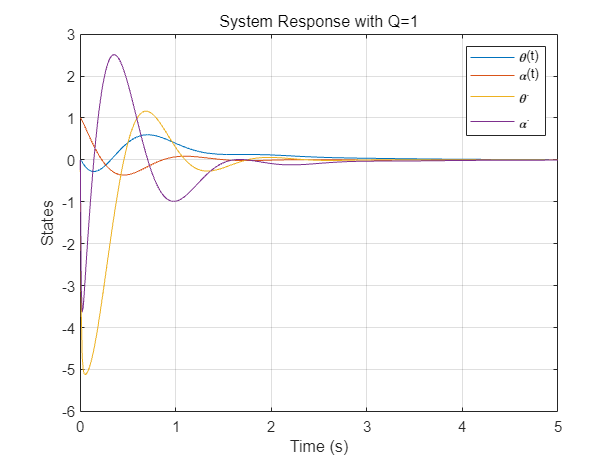

A = [0 0 0 1;
     0 0 1 0;
     0 81.4033 -45.8259 -0.9319;
     0 122.0545 -44.0906 -1.3972];
B = [0; 0; 83.4659; 80.3162];

Q = diag([1 1 1 1]);

R = 1;

[K, ~, ~] = lqr(A, B, Q, R);

x0 = [0 1 0 0];

t = 0:0.01:5;

sys = ss(A - B*K, [], [], []);

[~,~,x] = initial(sys, x0, t);
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('States');
legend('\theta(t)', '\alpha(t)', '\theta^.', '\alpha^.');
title('System Response with Q=1');
grid on;

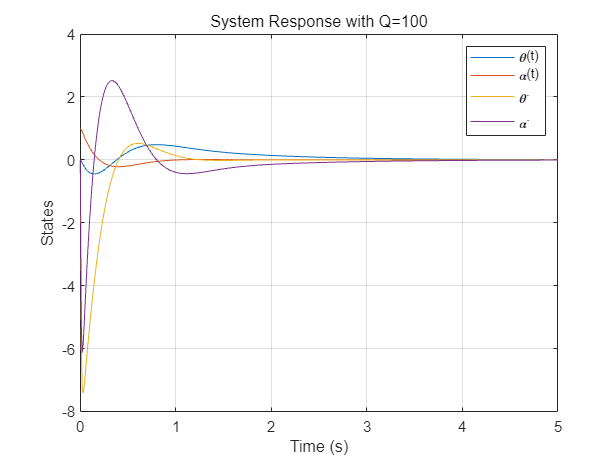

A = [0 0 0 1;
     0 0 1 0;
     0 81.4033 -45.8259 -0.9319;
     0 122.0545 -44.0906 -1.3972];
B = [0; 0; 83.4659; 80.3162];

Q = diag([1 100 1 1]);

R = 1;

[K, ~, ~] = lqr(A, B, Q, R);

x0 = [0 1 0 0];

t = 0:0.01:5;

sys = ss(A - B*K, [], [], []);

[~,~,x] = initial(sys, x0, t);
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('States');
legend('\theta(t)', '\alpha(t)', '\theta^.', '\alpha^.');
title('System Response with Q=100');
grid on;

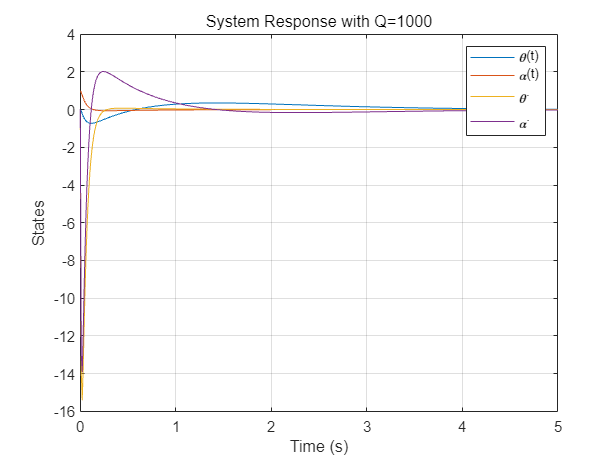

A = [0 0 0 1;
     0 0 1 0;
     0 81.4033 -45.8259 -0.9319;
     0 122.0545 -44.0906 -1.3972];
B = [0; 0; 83.4659; 80.3162];

Q = diag([1 1000 1 1]);

R = 1;

[K, ~, ~] = lqr(A, B, Q, R);

x0 = [0 1 0 0];

t = 0:0.01:5;

sys = ss(A - B*K, [], [], []);

[~,~,x] = initial(sys, x0, t);
figure;
plot(t, x);
xlabel('Time (s)');
ylabel('States');
legend('\theta(t)', '\alpha(t)', '\theta^.', '\alpha^.');
title('System Response with Q=1000');
grid on;